fileID = load("database\RECORDS");

file_name = int2str(fileID(15));
file_path = fullfile('database',file_name);
[signal,Fs,tm ]= rdsamp(file_path,1);

sig = signal(1:2000);
t = tm(1:2000);
windowSize = 5; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
sig1 = filter(b,a,sig);

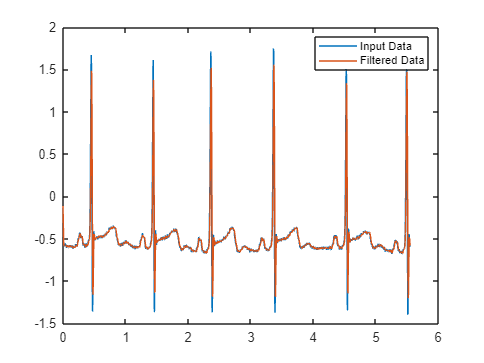

plot(t,sig)
hold on
plot(t,sig1)
hold off
legend('Input Data','Filtered Data')

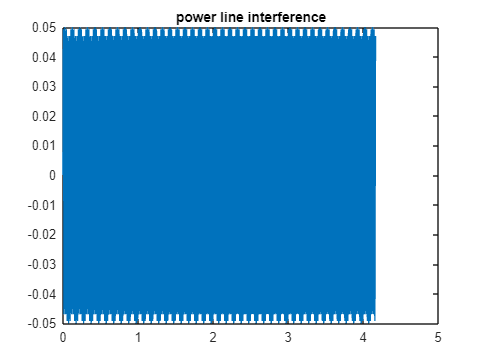

power_line_interference = 0.05 * sin(2*pi*50*t);
plot(t(1:1500),power_line_interference(1:1500))
title("power line interference")

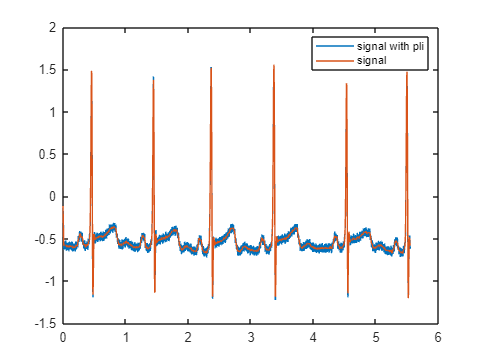

sig_pli = sig1 + power_line_interference;
plot(t,sig_pli)
hold on
plot(t,sig1)
hold off
legend('signal with pli','signal')

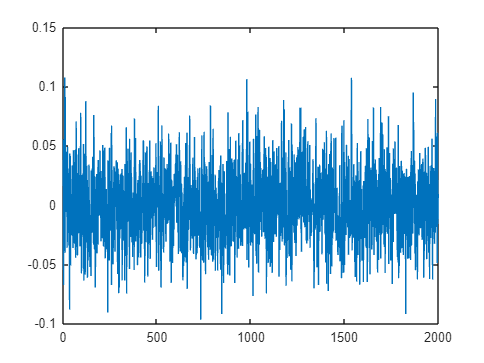

muscle_artifact = 0.03 * randn(size(t));  
plot(muscle_artifact)

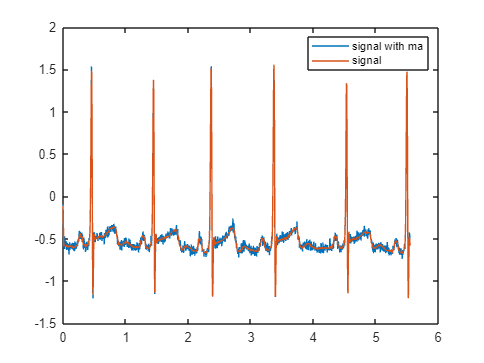

sig_ma = sig1 + muscle_artifact;
plot(t,sig_ma)
hold on
plot(t,sig1)
hold off
legend('signal with ma','signal')

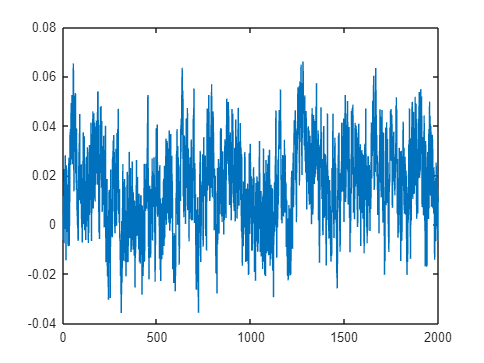

pink_noise = 0.7 * pinknoise(length(t));  % Amplitude: 0.3
plot(pink_noise)

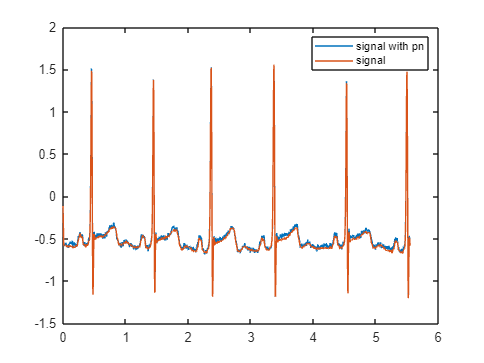

sig_pn = sig1 + pink_noise;
plot(t,sig_pn)
hold on
plot(t,sig1)
hold off
legend('signal with pn','signal')

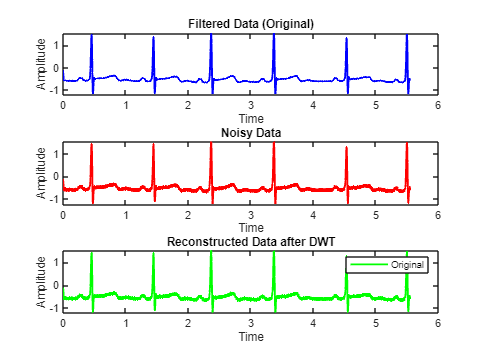

% Perform Discrete Wavelet Transform (DWT)
wavelet = 'db9'; % Choose a wavelet type (you can change this)
level = 3; % Choose the number of decomposition levels (you can change this)

% Perform DWT on the noisy signal
[c, l] = wavedec(sig_pli, level, wavelet);

% Apply soft thresholding to the wavelet coefficients
c_thresh = wthresh(c, 's', 0.5);

% Reconstruct the signal from the DWT coefficients
reconstructed_signal = waverec(c, l, wavelet);

% Plot the original filtered data, noisy data, and reconstructed data
figure;
subplot(3,1,1);
plot(t, sig1, 'b', 'LineWidth', 1.5);
title('Filtered Data (Original)');
xlabel('Time');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, sig_pli, 'r', 'LineWidth', 1.5);
title('Noisy Data');
xlabel('Time');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, reconstructed_signal, 'g', 'LineWidth', 1.5);
title('Reconstructed Data after DWT');
xlabel('Time');
ylabel('Amplitude');

legend('Original', 'Noisy', 'Reconstructed');

figure;